# Proyecto 2

## Juan Pablo Arango - Allan Torres

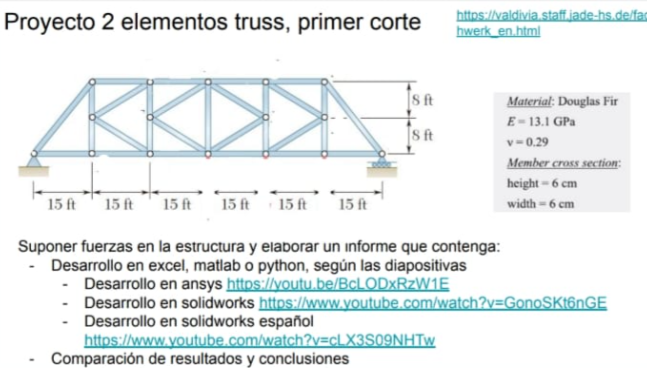

## Initial parameters (red for elements & blue for nodes)

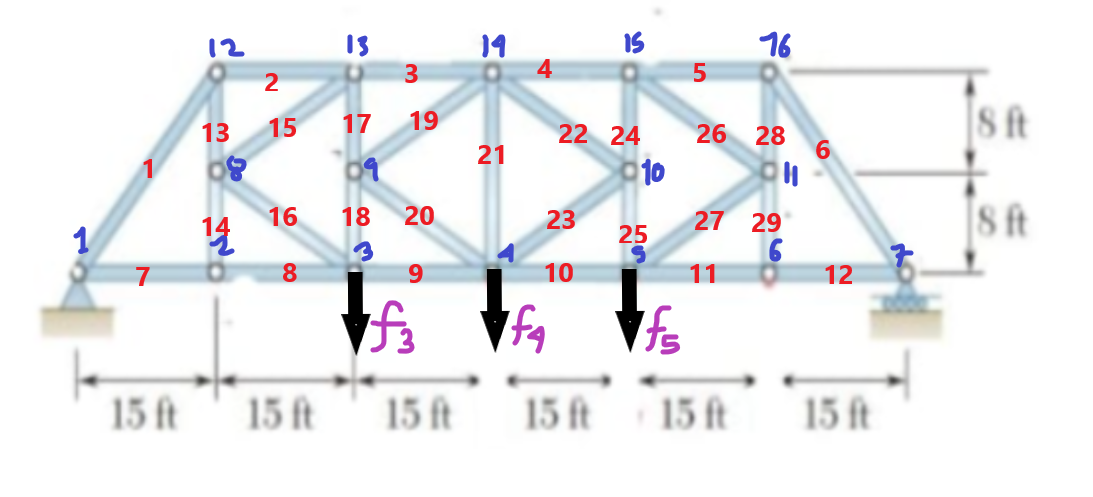

clear all
clc
syms f3 f4 f5 fx1 fy1 fy7 k1 k2 k3 k4 k5 k6 k7 k8 k9 k10 k11 k12 k13 k14 k15 k16 k17 k18 k19 k20 k21 k22 k23
f3=-3000; f4=-3000; f5=-3000;
ks= sym('K%d',[1 29]);
xstrain=sym('ox%d',[1 16]);%%Symbolic for all strains of which reactions will make o_x7=0 o_x1=0
xstrain(7)=0;
xstrain(1)=0;
ystrain=sym('oy%d',[1 16]);%% o_y6=0 and o_y1=0
ystrain(1)=0;
ystrain(6)=0;
%% f3 f4 and f5 are assumed forces while fy1 and fx1 are reactions from the support type at the left and fy2 is the reaction of roll support at the  right
Area=0.0036;%calculates transverse area
angles=[atan(16/15) atan(8/15)];%%Rising angles for each type of element
h1=hypot(16,15); %Large Hypotenuse value
h=hypot(8,15);% Short Hypotenuse value
elements=[1,12; 12,13;13,14;14,15;15,16;16,7;1,2;2,3;3,4;4,5;5,6;6,7;8,12;8,2;8,13;8,3;9,13;9,3;9,14;9,4;4,14;10,14;10,4;10,15;10,5;11,15;11,5;11,16;11,6];
Forces=sym(zeros(1,32));
Forces(1)=fx1; 
Forces(2)=fy1; 
Forces(2*3+2)=fy7; 
Forces(2*2+1)=f3;
Forces(2*3+1)=f4;
Forces(2*4+1)=f5;
strains=sym(zeros(1,32));
c=0;
for i= 1:32%% Loop to join the x y strains in one vector
  if mod(i,2)==0
      strains(i)=ystrain(i/2);
  else
      c=c+1;
      strains(i)=xstrain(c);
  end

end
E=13.1e6;

E = 13100000

v=0.29;


## Considerations:

As observed in the figure,

**Elements 2, 3, 4, 5, 7, 8, 9, 10, 11, 12 will be equal in lenght and angle, therefore, its K matrix will be the same**

**Elements 13, 14, 17, 18, 24, 25, 28, 29 will have an equal K**

**Elements 15, 19, 23, 27 will have an equal K**

**Elements 16, 20, 22, 26 will have an equal K**

% Group 1
ks(1)= LocalMatrix(Area,angles(1),h1,E);

X =      0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


ans = 1.0e+03 *

    2.1499    0.0307   -2.1499   -0.0307
    0.0307    0.0004   -0.0307   -0.0004
   -2.1499   -0.0307    2.1499    1.5686
   -0.0307   -0.0004    0.0307    0.0004


Unable
to
perform
assignment
because
the
left
and
right
sides
have
a
different
number
of
elements.

Error in sym/privsubsasgn (line 1307)
            L_tilde2 = builtin('subsasgn',L_tilde,struct('type','()','subs',{varargin}),R_tilde);

Error in indexing (line 1138)
            C = privsubsasgn(L,R,inds{:});

% Group 2
ks(2)= LocalMatrix(Area, 0, 15, E);%% Calculate K factor
ks(3)=ks(2); ks(4)=ks(2); ks(5)=ks(2); ks(7)=ks(2); ks(8)=ks(2); ks(9)=ks(2);ks(10)=ks(2);ks(11);ks(12)=ks(2);
% Group 3
ks(13)= LocalMatrix(Area, 90, 8, E);
ks(14)=ks(13); ks(17)=ks(13); ks(18)=ks(13); ks(24)=ks(13); ks(25)=ks(13); ks(28)=ks(13); ks(29)=ks(13);
% Group 4
ks(15)= LocalMatrix(Area, angles(2), h, E);
ks(19)=ks(15); ks(23)=ks(15); ks(27)=ks(15);
% Group 5
ks(16)= LocalMatrix(Area, 180-angles(2), h, E);
ks(20)=ks(16); ks(22)=ks(16); ks(26)=ks(16);
% Group 6
ks(6)= LocalMatrix(Area, 180-angles(1), h1, E);


## Filling the general matrix with each contibution given by each local matrix in relation of F to O (Force to strain)

Mgen=zeros(32,32);%% Declaration of (nodes*2 x nodes*2) general matrix
for i=1:lenght(elements)
    Mgen=ComparativeMatrix(i,Mgen); %% Description on function declaration  
end
Mgen;
eqns= Forces==Mgen*strains;
res= solve(eqns)%% Solve the system


## Functions

function X= LocalMatrix(A,AN,L,E)%% Where (Area, Angle, Lenght, Elasticity Modulus)
    el=[cosd(AN)^2          cosd(AN)*sind(AN)  -(cosd(AN)^2)       -cosd(AN)*sind(AN);
        cosd(AN)*sind(AN)   sind(AN)^2         -cosd(AN)*sind(AN)  -(sind(AN)^2);
        -(cosd(AN)^2)       -cosd(AN)*sind(AN)   cosd(AN)^2          cosd(AN)*sin(AN);
        -cosd(AN)*sind(AN)  -(sind(AN)^2)      cosd(AN)*sind(AN)    sind(AN)^2];
    X=zeros(4,4)
    (E*A/L)*el
    X=(E*A/L)*el;
end
function ExpandedMatrix= ComparativeMatrix(index,ZM) %% Where index refers to the element number evaluated with K and ZM the general square matrix (node*2 dimensions)
    global elements ks
    Kaux=ks(index);
    for subindex=1:2
        for row= 1:2
           for col= 1:32
               ZM(elements(index,subindex),col)=Kaux(row,col)+ZM(elements(index,subindex),col);
           end
        end
    end
    ExpandedMatrix=ZM;
    %%For each element, the function will search in the correspondant K the values of Xrow and Yrow that relate the strenght with the
    %%strain, this will be done for both subindexes used. For example a
    %%relation amongst F1 and F2 will be F1x F1y F2x F2y where the function
    %%will find the values in the k matrix that relarte F1x with o1x, F2x
    %%with o2x and so on. Once found it will put them inside the general matrix
    %%added to the value of the cell it belongs to
    
end